# Export Stateful Predict Block from Deep Network Designer into Simulink

load("compressedNet.mat")

Use Deep Network Designer to view the network. 

deepNetworkDesigner(netFineTuned); 

Use the export functionality to create a Simulink model with Stateflow Predict block. 

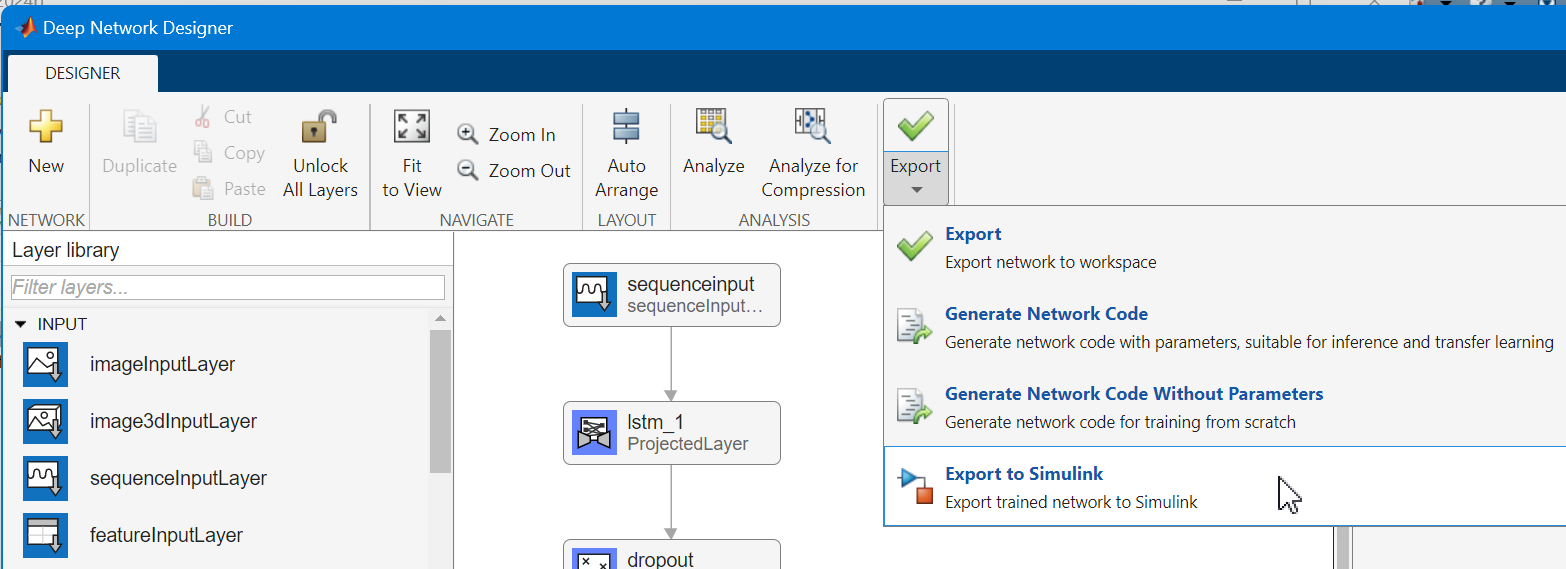

Add Inport and Outport blocks to drive the network with correct sizes and types. 

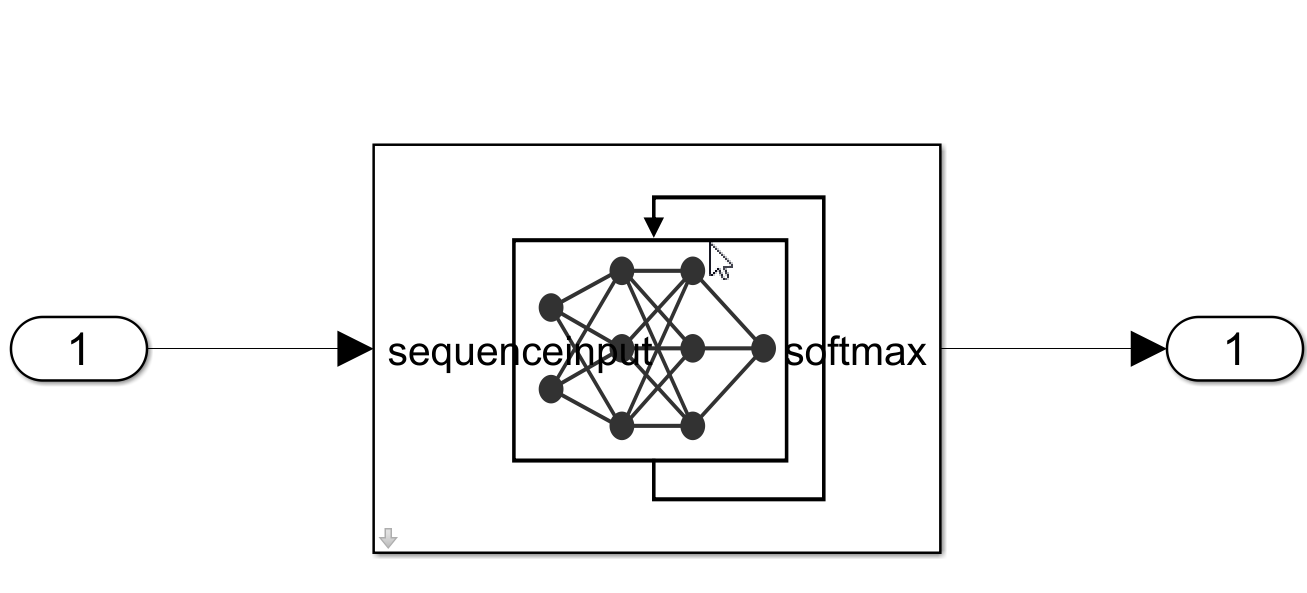

Generating code from this model following the same "quick start" steps. Or, you can use the attached model in this directory. 

unPackedNet = unpackProjectedLayers(netFineTuned); 
save("unpacked.mat", "unPackedNet"); 
open_system("generated_predictBlock"); 